# Tanque Cilíndrico Horizontal

Se considera la posibilidad de colocar el tanque de combustible de manera acostada.

clear
close all
clc

Tiempo de simulación

tf=18;                %horas
t=linspace(0,tf,21);  

Dimensiones Tanque Cilíndrico

g=127137600;          % Aceleración gravedad m h^-2
DT=25;                % m Diámetro tanque 
H=4;                  % m Altura tanque
Dsm=0.0254*3;         % m^2 Válvula de salida diámetro 3 in 
C=80/100;             % Fracción nominal de ocupación
AT=pi*DT^2/4;         % m^2 Área sección transversal
V0=C*H*AT;            % Volumen inicial

Tanque parado

c=sqrt(2*g)*(Dsm/DT)^2; % Constante c
h0=C*H;                 % Nivel inicial del líquido
h=(sqrt(h0)-c*t/2).^2;  % Modelo de descarga
VP=V0-AT*h;             % Volumen perdido

Tanque acostado

L=DT^2/H              % m Longitud necesaria para contener el mismo volumen acostado que parado    

L = 156.2500

r=H/2;               
aTt=pi*r^2;           % m^2 Área transversal total
aT=@(h)r^2*acos((r-h)/r)-(r-h).*sqrt(2*r*h-h.^2);

Determinación de altura inicial

ff=@(x)(r^2*acos((r-x)/r)-(r-x)*sqrt(2*r*x-x^2))/aTt-C;
D0=fzero(ff,C*H)

D0 = 2.9837

Cálculo modelo

K=pi*Dsm^2*sqrt(2*g)/(8*L);
hh=H-(3*K*t/2+(H-D0)^(3/2)).^(2/3);
VA=V0-L*aT(hh);

Graficado

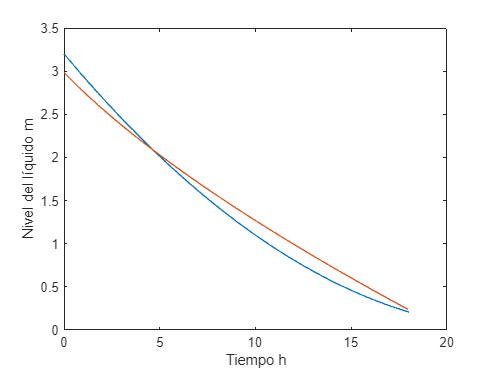

plot(t,h,t,hh)
xlabel('Tiempo h')
ylabel('Nivel del líquido m')

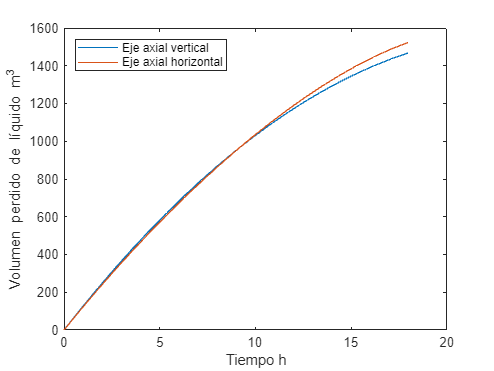

plot(t,VP,t,VA)
ylim([0 1600])
xlabel('Tiempo h')
ylabel('Volumen perdido de líquido m^3')
legend('Eje axial vertical','Eje axial horizontal','Location','northwest')